% Define the "base case" as described in paper:

% Environment:
w0=100;     % Initial wealth
G=200;      % Goal wealth
T=10;       % Time horizon (10 years)

% Portfolios:
num_pf=15;        % Number of MV efficient portfolios
rho_g=3.0;   % Grid point density per min annual std in pf performance

% Emperical Index Fund metrics

% for: U.S. Bonds | International Stocks | U.S. Stocks
m = [0.0493 0.0770 0.0886]'; % Index funds mean return

Sigma =   [0.0017 -0.0017 -0.0021;
            -0.0017 0.0396 0.0309;
            -0.0021 0.03086 0.0392]; % Index funds covariance matrix


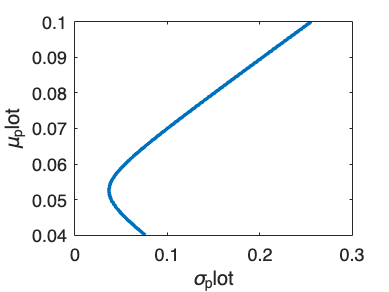

% Compute the Efficient Frontier (as per Sec 2.2)

n = numel(m); % Number of index funds
o = ones(n,1);
Sigma_inv = Sigma \ eye(n);

% Define constants
k = m' * Sigma_inv * o;
l = m' * Sigma_inv * m;
p = o' * Sigma_inv * o;

% Define Vectors
g = (l * (Sigma_inv * o) - k * (Sigma_inv * m)) / (l*p - k^2);
h = (p * (Sigma_inv * m) - k * (Sigma_inv * o)) / (l*p - k^2);

% Define constants for hyperbola
a = h' * Sigma * h;
b = 2 * (g' * Sigma * h);
c = g' * Sigma * g;


mu_plot = linspace(0.04, 0.1, 200);     % or [mu_min, mu_max]
sigma_plot = sqrt(a*mu_plot.^2 + b*mu_plot + c);

figure;
plot(sigma_plot, mu_plot, 'LineWidth', 2);
xlabel('\sigma_plot'); ylabel('\mu_plot'); 


mu_min = k / p 

mu_min = 0.0525

mu_max = max(m)

mu_max = 0.0886

mu_vec = linspace(mu_min,mu_max,num_pf);

% Get weights of index fund portfolios
W = zeros(length(mu_vec), length(g));
for i = 1:length(mu_vec)
    mu = mu_vec(i);
    W(i,:) = (g + mu * h)';     
end

% For reference:
W_paper = [...
    0.9098 0.0225 0.0677;
    0.8500 0.0033 0.1467; 
    0.7903 -0.0160 0.2257;
    0.7305 -0.0352 0.3047;
    0.6707 -0.0545 0.3837;
    0.6110 -0.0737 0.4628; 
    0.5512 -0.0930 0.5418; 
    0.4915 -0.1122 0.6208; 
    0.4317 -0.1315 0.6998; 
    0.3719 -0.1507 0.7788; 
    0.3122 -0.1700 0.8578; 
    0.2524 -0.1892 0.9368; 
    0.1927 -0.2085 1.0158; 
    0.1329 -0.2277 1.0948; 
    0.0731 -0.2470 1.1738];

% Compute vmu and vsi:
% vmu: 15x1 vector of portfolio mean returns
vmu = W * m;   

% vsi: 15×1 vector of portfolio standard deviations
vsi = sqrt(sum((W * Sigma) .* W, 2));

% Build grid:
nw = 327; % Number of wealth nodes, chosen by paper.

[w, lw] = grid(w0, T, nw, rho_g, vmu, vsi, G);


% Dynamic Programming

% Transition Probabilities:

P = zeros(nw, nw, num_pf); % P(i,j,k) = p( Wealth_j(t+1) | Wealth_i(t), portfolio k )

ctpm = zeros(nw, nw, num_pf);      % cumulative transition probabilities
start_ctpm = zeros(nw, num_pf);    % cumulative transitions starting from w0

for k = 1:num_pf
    mu_k = vmu(k);
    si_k = vsi(k);
    drift_k = mu_k - 0.5 * si_k^2; 

    % transitions from each wealth grid node
    for i = 1:nw
        Wi = w(i);
        z = (log(w ./ Wi) - drift_k) ./ si_k; % EQN 6 from paper
        p = normpdf(z);
        p = p ./ sum(p);              % normalize to sum to 1
        P(i,:,k) = p;                 % store transition probabilities
        ctpm(i,:,k) = cumsum(p);      % store cumulative probabilities
    end

    % transitions starting from actual initial wealth w0 (not on the grid)
    z0 = (log(w ./ w0) - drift_k) ./ si_k;
    p0 = normpdf(z0);
    p0 = p0 ./ sum(p0);
    start_ctpm(:,k) = cumsum(p0);
end

% Value function:
V = zeros(nw, T+1);         % V(: , time index)
policy = zeros(nw, T);      % store optimal portfolio index at each (i,t)

% Terminal condition at t = T  -> column index T+1
V(:, T+1) = double(w >= G);

% Bellman Recursion
for t = T:-1:1        % Start at T and go to 1
    V_next = V(:, t+1);     

    for i = 1:nw
        EV = zeros(num_pf,1);

        % Expected value under each portfolio
        for k = 1:num_pf
            EV(k) = P(i,:,k) * V_next;
        end

        [V(i,t), policy(i,t)] = max(EV); % Choose best pf
    end
end

[~, i0] = min(abs(w - w0)); % Find the node closest to w0
prob_hit_goal_raw = V(i0, 1) % N0 interpolation

prob_hit_goal_raw = 0.6692


% Interpolate:
iL = find(w <= w0, 1, 'last'); % Find the largest node still less than w0
iU = iL + 1; % Get the next node (greater than w0)

wL = w(iL)  

wL = 99.8903

wU = w(iU) %Get the node value

wU = 101.1476

VL = V(iL,1); % Lower prob
VU = V(iU,1); % Higher Prob

alpha = (w0 - wL) / (wU - wL);

prob_hit_goal_inter = VL + alpha * (VU - VL) % Linear interpolation

prob_hit_goal_inter = 0.6702

% OOS Approach (Use optimal Policy)

Nsim = 1000000;
success = 0;
W_final = zeros(Nsim,1);

% choose the first-period action using the nearest grid node to w0
[~, i0] = min(abs(w - w0));
k0 = policy(i0, 1);

for s = 1:Nsim
    % Step 1: draw first grid node from w0 using start_ctpm
    u = rand;
    j = find(start_ctpm(:, k0) >= u, 1, 'first');
    idx = j;                 % current wealth index on the grid

    % Steps 2..T using ctpm and policy
    for t = 2:T
        k = policy(idx, t);  % optimal action at (idx, t)
        u = rand;
        idx = find(ctpm(idx, :, k) >= u, 1, 'first');
    end

    Wealth = w(idx);         % final wealth lives on grid
    W_final(s) = Wealth;
    success = success + (Wealth >= G);
end

p_out_of_sample = success / Nsim;
fprintf('OOS success prob. = %.6f\n', p_out_of_sample);

OOS success prob. = 0.670215


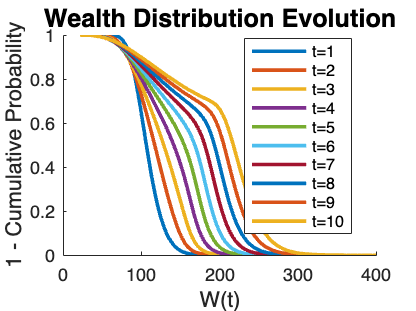

% Build Figure 2

p = zeros(nw, T+1);
[~, i0] = min(abs(w - w0));
p(i0,1) = 1;

for t = 1:T
    p_next = zeros(nw,1);

    for i = 1:nw
        k = policy(i,t);                 % optimal portfolio at node i, time t
        p_next = p_next + p(i,t) * squeeze(P(i,:,k))';
    end

    p(:,t+1) = p_next;
end

CCDF = zeros(nw, T+1);

for t = 1:T+1
    CDF = cumsum(p(:,t));    % cumulative sum over wealth
    CCDF(:,t) = 1 - CDF;     % probability of having AT LEAST w
end

figure; hold on;
colors = lines(T);

for tau = 1:T
    t_idx = tau + 1;  
    plot(w, CCDF(:, t_idx), 'LineWidth', 2, 'Color', colors(tau,:));
end

xlabel('W(t)', 'FontSize', 12);
ylabel('1 - Cumulative Probability', 'FontSize', 12);
title('Wealth Distribution Evolution', 'FontSize', 14);

legendStrings = arrayfun(@(x) sprintf('t=%d', x), 1:T, 'UniformOutput', false);
legend(legendStrings, 'Location', 'best');
xlim([0 400]);

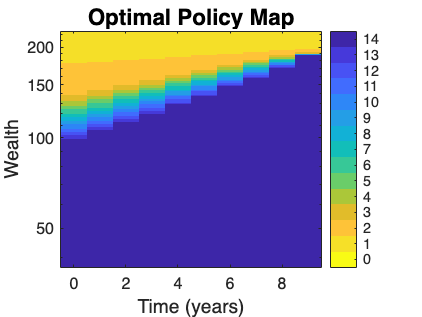

% Numerical Experiments

% Figure 4:
figure; 
imagesc(0:T-1, w, policy); 
set(gca,'YDir','normal');  % wealth increases upward
ylim([37 226]);
set(gca, 'YScale', 'log');
% Start from parula, but flip it so low values are light, high are dark
cmap = flipud(parula(num_pf));
colormap(cmap);
caxis([-0.5, num_pf-0.5]);           % centers color bins at 0,1,...,14

% Colorbar with integer tick labels
cb = colorbar;
cb.Ticks = 0:(num_pf-1);             % 0..14
cb.TickLabels = 0:(num_pf-1);

xlabel('Time (years)','FontSize',12);
ylabel('Wealth','FontSize',12);
title('Optimal Policy Map','FontSize',14);